clc;
clear all;
imageName='san_antonio_no_soleado.tif';
fileNameDSM="san_antonio_no_soleado-dsm.tif";
task="80b83c54-367c-4eee-8eed-8139a96a8ad6";
lote=3;
imagenRGB=obtenerImageSegmented(imageName);

%imageSegmented=segmentarPorKmeans(3,3,imagenRGB);


% Segmentar mediante Color Thresold
[imageSegmented] =segmentImageUsingColorThreshold(imagenRGB,true);

Aplicación de gradiente

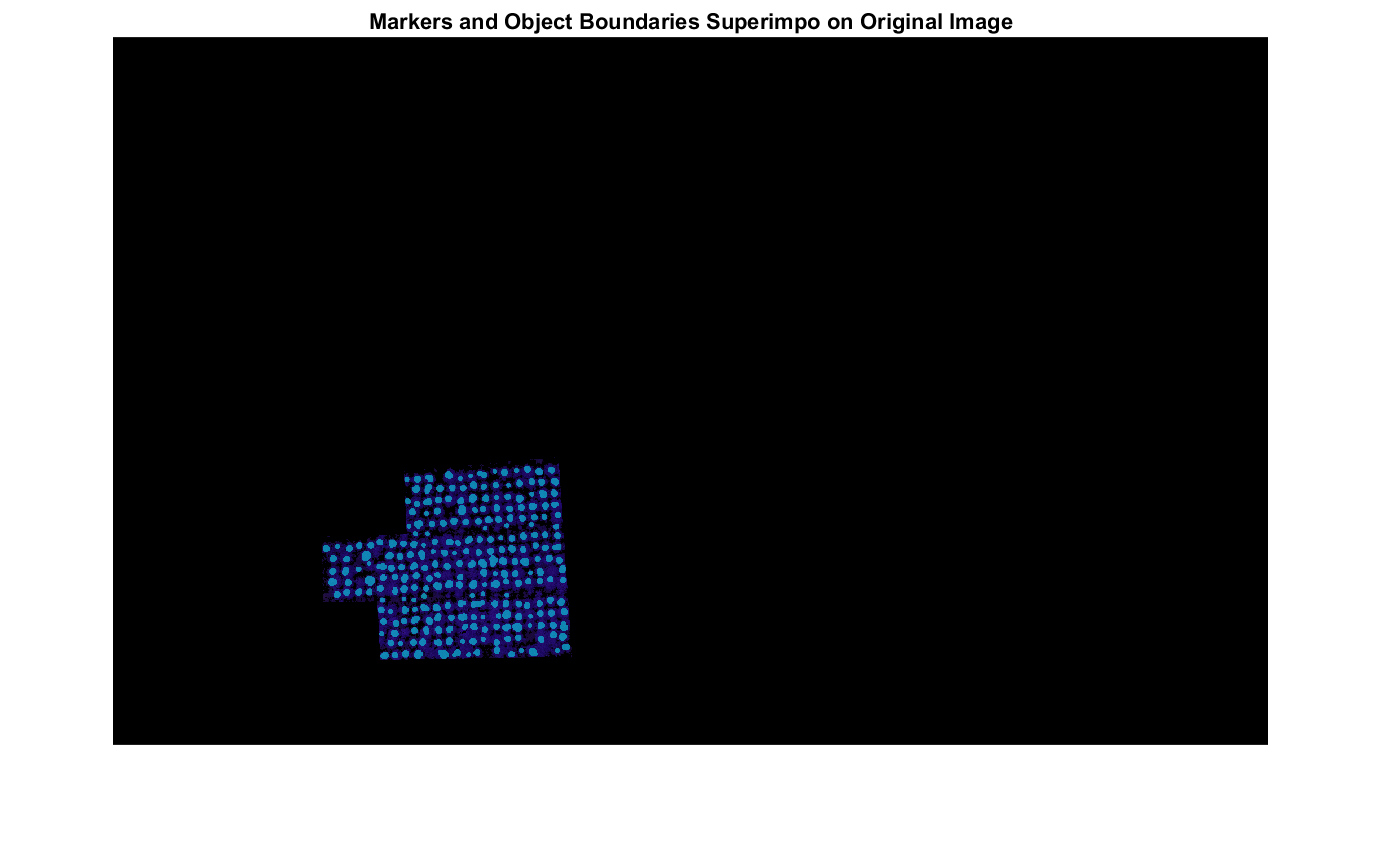

[fgm4,gmag] =ejecutarWatershedForegroundMarkersProcess(imageSegmented);

labelsToImage = 3*fgm4;
I4 = labeloverlay(imageSegmented,labelsToImage);
imshow(I4)
title('Markers and Object Boundaries Superimpo on Original Image')

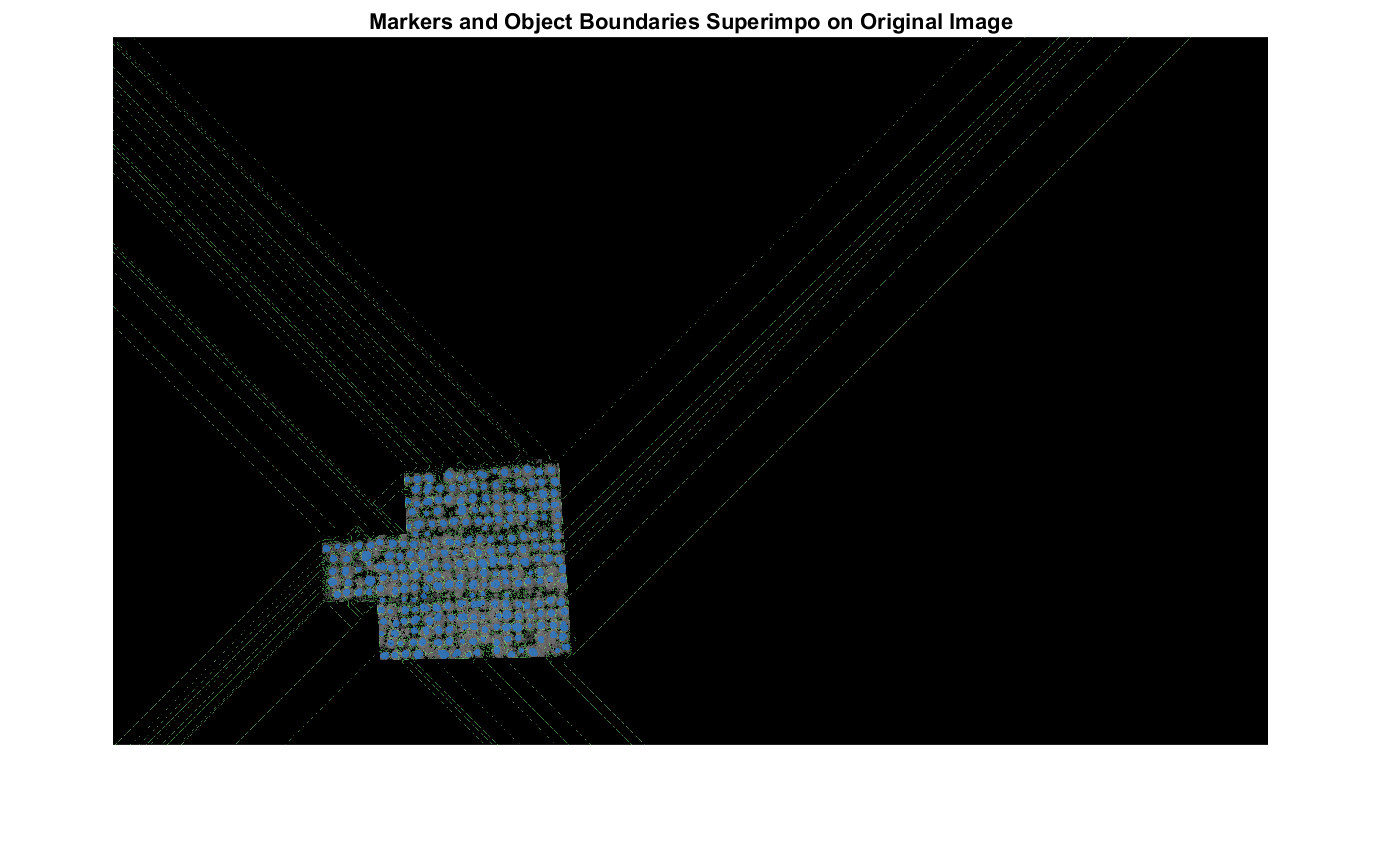


labels=ejecutarWatershedBackgroundMarkers(fgm4,gmag,segmentImageUsingColorThreshold(imagenRGB,false));

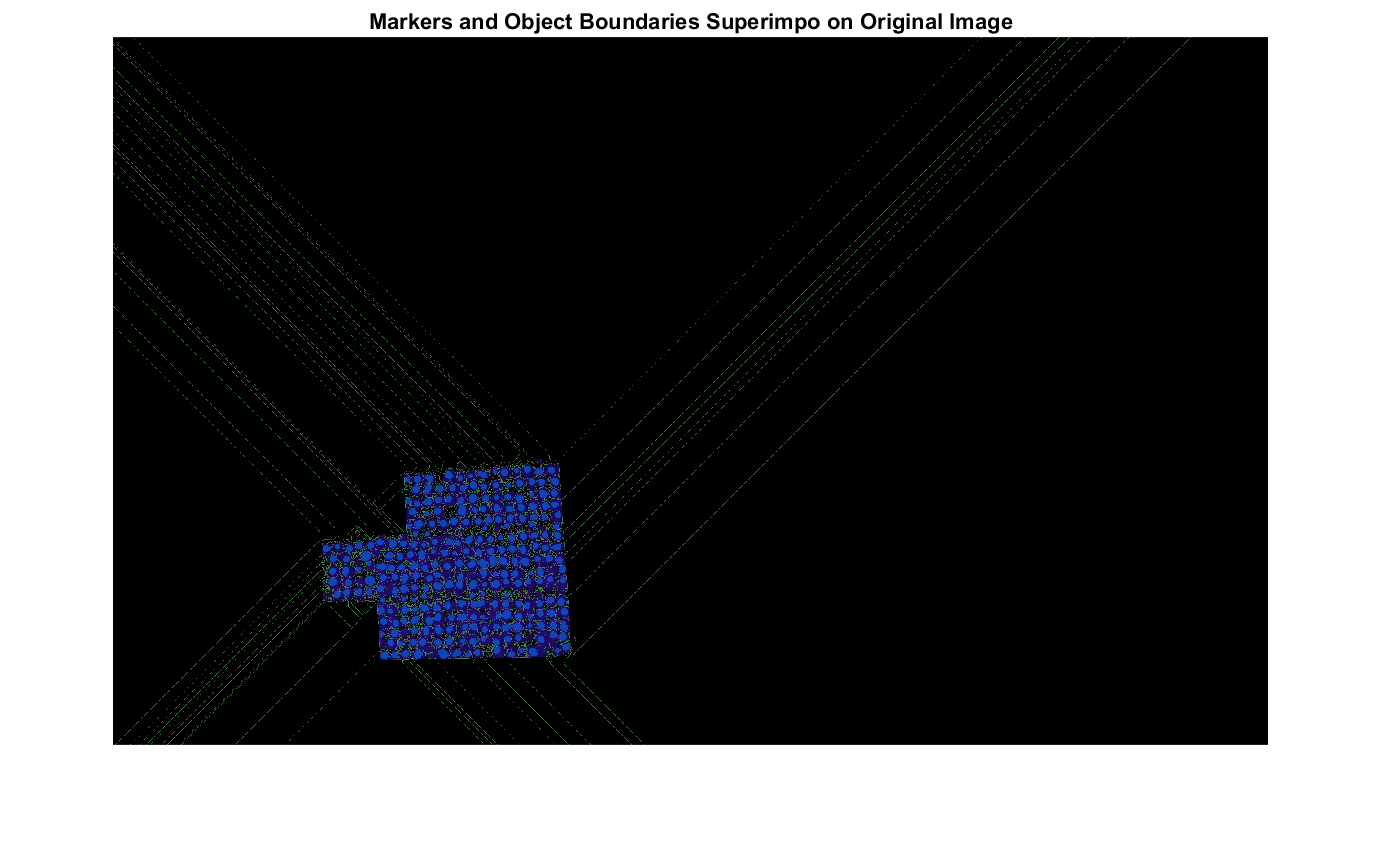

 
labelsToImage = imdilate(labels==0,ones(3,3))+ 3*fgm4;
I4 = labeloverlay(imageSegmented,labelsToImage);
imshow(I4)
title('Markers and Object Boundaries Superimpo on Original Image')

procesarLabelsResult(labels,segmentImageUsingColorThreshold(imagenRGB,false),imageName,lote,task,fileNameDSM);